# ELL7420 Design Assignment 2 - Pitch detection by autocorrelation and by cepstrum

Two pitch detectors, explained alongside the MATLAB code and compared on the same speech samples.

- **Time domain - autocorrelation.** How well does a frame of speech match a delayed copy of itself? The delay that matches best is the pitch period.

- **Frequency domain - cepstrum.** A voiced frame has harmonics at a regular spacing in its spectrum. The cepstrum measures that spacing, which again gives the pitch period.

Both methods are given the same 40 ms frames on the same 10 ms grid, the same quiet-frame check and the same peak picker. They differ only in the curve that is searched for a peak, so a difference in the results comes from the methods themselves.

Run this Live Script with the speech samples folder beside it or one level up. The results folder will contain four CSV files, p3.mat, p4.mat and eight plots.

## 1. The data and where the results go

We have four speech files: s1.wav, s2.wav, s3.wav and s4.wav. The p1.mat and p2.mat files give reference pitch values for s1 and s2 every 10 ms. A zero in the reference means unvoiced or silence. There are no reference pitch files for s3 and s4.

The code checks both speech samples and speech_samples next to this Live Script and one level up. It also checks for an extra nested folder created by a ZIP extractor. If it still cannot find s1.wav, MATLAB opens a folder picker: select the folder that directly contains the WAV files. The code then prepares results/report_plots for saved figures.

base = fileparts(mfilename('fullpath'));
% Check the common folder names next to the Live Script and one level up.
parents = {base, fullfile(base,'..')};
names = {'speech samples','speech_samples'};
data = '';
for p = 1:numel(parents)
    for n = 1:numel(names)
        folder = fullfile(parents{p},names{n});
        options = {folder,fullfile(folder,'speech_samples'), ...
                   fullfile(folder,'speech samples')};
        for q = 1:numel(options)
            if isfile(fullfile(options{q},'s1.wav'))
                data = options{q};
                break;
            end
        end
        if ~isempty(data), break; end
    end
    if ~isempty(data), break; end
end
if isempty(data)
    % If the folder is elsewhere, select the folder that has s1.wav inside.
    data = uigetdir(base,'Select the folder containing s1.wav');
    assert(~isequal(data,0),'No speech samples folder was selected');
end
assert(isfile(fullfile(data,'s1.wav')), ...
       'Please select the folder that directly contains s1.wav');
fprintf('Reading speech files from: %s\n',data);

Reading speech files from: C:\Users\NAVY\Desktop\IITD MSR\Courses\ELL7420-ADSP\Design Assignment-2\ADSP-2\v4\..\speech_samples


out = fullfile(base,'results');
plots = fullfile(out,'report_plots');
if ~isfolder(plots), mkdir(plots); end

% Save every plot on a white background, whatever theme the MATLAB desktop uses.
appearance = settings;
appearance.matlab.appearance.figure.GraphicsTheme.TemporaryValue = 'light';

## 2. Read the four recordings and estimate pitch with both methods

We use audioread to get the samples x and the sampling rate fs. If the file has two audio channels, we average them to get one signal. Then track_pitch (autocorrelation) and track_pitch_cepstrum (cepstrum) each move along the speech and produce one estimate every 10 ms: a pitch in Hz, or 0 where the frame is judged unvoiced.

Each raw track is then passed through the same 5-frame median filter (Section 7). For s1 and s2 we also load the given reference. Only s1 and s2 can be scored; for s3 and s4 the two tracks are the result.

rng(0); % Only the noise test in Section 11 uses random numbers.
for s = 1:4
    [x,fs] = audioread(fullfile(data,sprintf('s%d.wav',s)));
    x = mean(x,2); % Average channels if the recording is stereo.
    speech{s} = x;
    [time,rawAcf{s}] = track_pitch(x,fs);
    [~,rawCep{s}] = track_pitch_cepstrum(x,fs);
    acf{s} = smooth_track(rawAcf{s});
    cep{s} = smooth_track(rawCep{s});
    reference{s} = nan(size(time));

    % Only s1 and s2 have a supplied pitch track. Zero means unvoiced.
    if s <= 2
        key = sprintf('p%d',s);
        saved = load(fullfile(data,[key '.mat']));
        reference{s} = saved.(key); reference{s} = reference{s}(:);
        assert(numel(reference{s})==numel(time),'Reference length does not match');
    end
    fprintf(['s%d: voiced frames %d / %d of %d, median pitch %.0f / %.0f Hz ' ...
             '(autocorrelation / cepstrum)\n'],s,sum(acf{s}>0),sum(cep{s}>0), ...
             numel(time),median(acf{s}(acf{s}>0)),median(cep{s}(cep{s}>0)));
end

s1: voiced frames 159 / 155 of 300, median pitch 212 / 211 Hz (autocorrelation / cepstrum)
s2: voiced frames 163 / 177 of 300, median pitch 133 / 129 Hz (autocorrelation / cepstrum)
s3: voiced frames 174 / 168 of 300, median pitch 223 / 223 Hz (autocorrelation / cepstrum)
s4: voiced frames 145 / 122 of 300, median pitch 177 / 181 Hz (autocorrelation / cepstrum)


## 3. Time domain: what the autocorrelation pitch tracker does

We take a 40 ms frame for each point on a 10 ms grid. Overlapping frames give enough speech to see a repeating pattern while the answer still updates often. A frame starts at 0 Hz and receives a pitch only if it passes both checks.

The first check is RMS amplitude at least 0.008, so a very quiet frame is left unvoiced. The second check is a selected correlation peak of at least 0.50. These are the thresholds used in our code; they are not universal settings for every speaker.

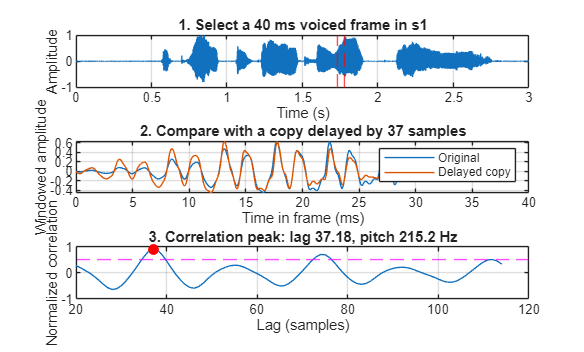

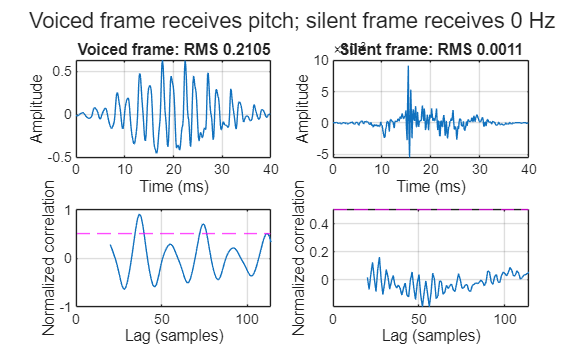

function [time,pitch] = track_pitch(x,fs)

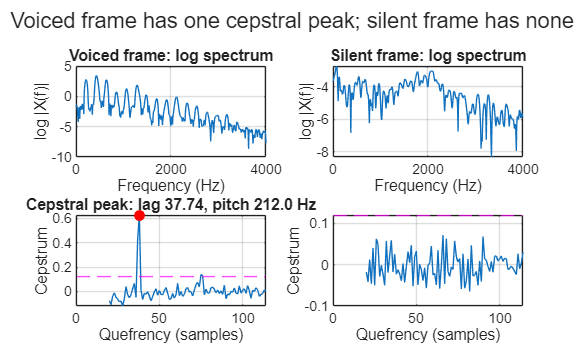

    % Work every 10 ms so our estimates line up with p1/p2.

    % Use 0 Hz when a frame does not pass the voiced tests.
    hop = round(.01*fs);
    count = ceil(numel(x)/hop);
    time = ((0:count-1)'*hop+floor(hop/2))/fs;
    pitch = zeros(count,1);
    for i = 1:count
        [~,lags,r,energy] = frame_correlation(x,fs,i);
        if energy < .008, continue; end % Too quiet to give a useful pitch.
        [period,strength] = best_period(lags,r);
        % A regular speech cycle should give a strong correlation peak.
        if strength >= .50, pitch(i) = fs/period; end
    end
end

## 4. Prepare one frame and compare delayed copies

We centre the 40 ms frame at the current time point and pad with zeros at the start or end of the recording if needed. We subtract the mean to remove a constant offset, then apply a Hamming window to reduce the effect of the frame edges.

Autocorrelation asks: how well does this frame match a delayed version of itself? At lag k, we multiply the overlapping samples from the original and delayed copies, add those products, and divide by the energies of both copies. Normalising helps stop amplitude alone from controlling the match.

We search lags corresponding approximately to 70-400 Hz. If a repeated speech cycle is present, its period should give a strong peak in this range. The RMS value also tells us whether the frame is too quiet to trust.

function [frame,lags,r,energy] = frame_correlation(x,fs,i)
    % Take 40 ms around this frame's time point, padding at the ends.
    L = round(.04*fs); hop = round(.01*fs);
    index = (i-1)*hop+floor(hop/2)-floor(L/2)+(0:L-1)';
    valid = index>=0 & index<numel(x);


file   method           smoothing   TP  FP  FN   TN  precision  recall  MAE (Hz)  within 20%  frame error


    frame = zeros(L,1); frame(valid) = x(index(valid)+1);
    % Remove the mean and taper the edges before comparing delayed copies.
    window = .54-.46*cos(2*pi*(0:L-1)'/(L-1));
    frame = (frame-mean(frame)).*window;
    energy = sqrt(mean(frame.^2));
    % Pitch = fs/lag, so these lags cover roughly 70 to 400 Hz.
    lags = (ceil(fs/400):min(L-2,floor(fs/70)))';
    r = zeros(size(lags));
    for j = 1:numel(lags)
        k = lags(j); a = frame(1:end-k); b = frame(k+1:end);

s1     autocorrelation  none       147  13   9  131      91.9%   94.2%      7.16     143/156         8.7%
s1     autocorrelation  median     146  13  10  131      91.8%   93.6%      4.59     145/156         8.0%
s1     cepstrum         none       148   8   8  136      94.9%   94.9%      4.98     145/156         6.3%
s1     cepstrum         median     149   6   7  138      96.1%   95.5%      5.07     147/156         5.0%
s2     autocorrelation  none       160   2  15  123      98.8%   91.4%      5.69     156/175         7.0%
s2     autocorrelation  median     161   2  14  123      98.8%   92.0%      5.37     157/175         6.7%
s2     cepstrum         none       172   4   3  121      97.7%   98.3%      1.26     172/175         2.3%
s2     cepstrum         median     173   4   2  121      97.7%   98.9%      1.35     173/175         2.0%
s1+s2  autocorrelation  none       307  15  24  254      95.3%   92.7%      6.40     299/331         7.8%
s1+s2  autocorrelation  median     307  15  24

        % Normalise so loudness has less effect on the peak height.
        r(j) = sum(a.*b)/sqrt(sum(a.^2)*sum(b.^2)+1e-12);
    end
end

## 5. Pick the period and turn it into Hz

A correlation curve can peak at one period and at multiples of that period. We find the local peaks and take the earliest peak that reaches at least 82% of the strongest local peak. This favours a short convincing period.

The peak might fall between two sample positions, so we use its neighbouring values for a small parabolic adjustment. We limit that adjustment to half a sample. The pitch is then fs divided by the adjusted period in samples.

The cepstrum method in the next section hands its own curve to this same function, so both methods choose their peak by the same rule.

function [period,strength] = best_period(lags,r)


file  same decision   both voiced   within 5%    mean difference


    % Find local peaks, then take the first one close to the strongest peak.
    % This favours the shortest convincing period over its multiples.
    peaks = find(r(2:end-1)>r(1:end-2) & r(2:end-1)>=r(3:end))+1;
    period = NaN; strength = 0;
    if isempty(peaks), return; end
    peaks = peaks(r(peaks)>=.82*max(r(peaks)));
    j = peaks(1); strength = r(j);
    % Fit around the peak to estimate a lag between integer samples.
    curvature = r(j-1)-2*r(j)+r(j+1);
    shift = 0;

s1           94.0%           148       95.9%            2.93 Hz
s2           94.7%           162       95.1%            4.73 Hz
s3           97.3%           167       97.6%            2.24 Hz
s4           90.3%           119       93.3%            7.10 Hz


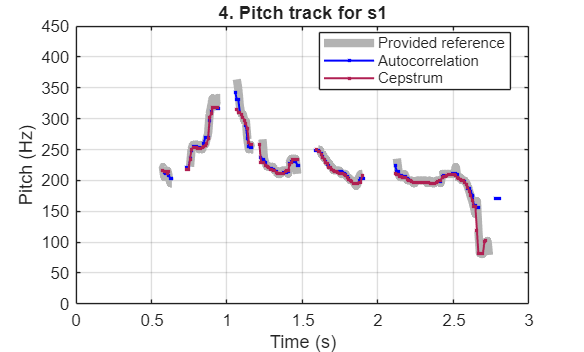

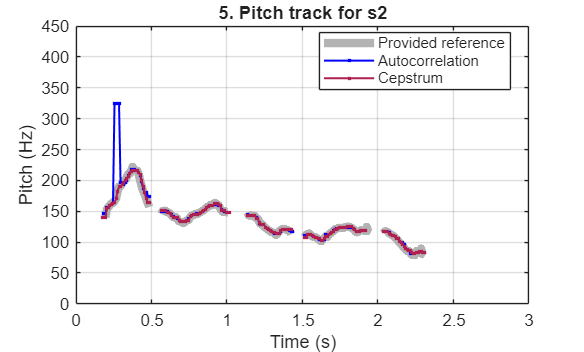

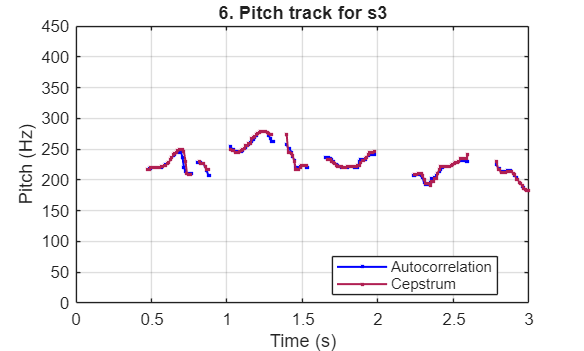

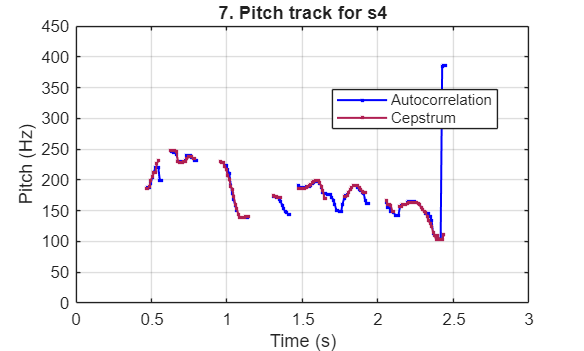

    if abs(curvature)>1e-12
        shift = .5*(r(j-1)-r(j+1))/curvature;
        shift = max(-.5,min(.5,shift));
    end
    period = lags(j)+shift;
end

## 6. Frequency domain: the cepstrum of the same frame

Voiced speech is a train of pulses from the vocal folds, shaped by the mouth and throat. In the spectrum of a frame the pulses appear as harmonics, evenly spaced at the pitch frequency, under a smooth envelope set by the mouth. The spacing of the harmonics is what we want to measure.

Taking the logarithm of the magnitude spectrum turns "harmonics times envelope" into "harmonic ripple plus envelope". The ripple repeats along the frequency axis once every pitch frequency. An inverse FFT of the log spectrum measures how tightly it ripples: a ripple that repeats every F0 Hz gives a peak at 1/F0 seconds, the pitch period. This inverse FFT of the log spectrum is the cepstrum, and its axis is called quefrency. We count it in samples, exactly like the lag of the autocorrelation.

The slow envelope lands at small quefrencies, below the search range, so it does not disturb the peak. We take the frame that frame_correlation already prepares (40 ms, mean removed, Hamming window), read the cepstrum at the same 70-400 Hz lags and pass it to the same best_period. A frame is voiced if it is not quiet (same RMS rule) and its cepstral peak is at least 0.12. An unvoiced frame has no harmonics, so no ripple and no peak.

function [time,pitch] = track_pitch_cepstrum(x,fs)
    % Same 10 ms grid, frames and quiet-frame rule as track_pitch.
    % Only the curve that is searched for a peak is different.
    hop = round(.01*fs);
    count = ceil(numel(x)/hop);
    time = ((0:count-1)'*hop+floor(hop/2))/fs;
    pitch = zeros(count,1);
    for i = 1:count
        [frame,lags,~,energy] = frame_correlation(x,fs,i);
        if energy < .008, continue; end % Too quiet to give a useful pitch.
        [period,strength] = best_period(lags,frame_cepstrum(frame,lags));
        % A voiced frame gives one clear cepstral peak; an unvoiced one gives none.
        if strength >= .12, pitch(i) = fs/period; end
    end
end

function [c,logSpectrum] = frame_cepstrum(frame,lags)
    % Cepstrum = inverse FFT of the log magnitude spectrum of the frame.
    logSpectrum = log(abs(fft(frame,1024))+eps);
    c = real(ifft(logSpectrum));
    % Quefrency q samples is element q+1. Keep the lags for 70 to 400 Hz.


Frame error on s1+s2 with added white noise (median-filtered tracks)


    c = c(lags+1);

SNR (dB)  autocorrelation   cepstrum


end

       0            35.3%      33.7%
       5            18.5%      21.8%
      10            11.9%      14.2%
      15             8.7%      11.1%
      20             7.4%       8.6%
      30             7.4%       5.1%


## 7. The same median filter for both tracks

A single frame can be wrong while its neighbours are right. A 5-frame median filter repairs that. A frame stays voiced only if most of the five frames around it are voiced, and its pitch becomes the middle value of the voiced ones among those five. We take the lower of the two middle values when their number is even, so the output is always a pitch that was actually measured, never an average of two.

The filter is applied to both methods. The tables below give the scores without it as well, so its effect can be seen.

function pitch = smooth_track(pitch)

   clean             7.3%       3.5%


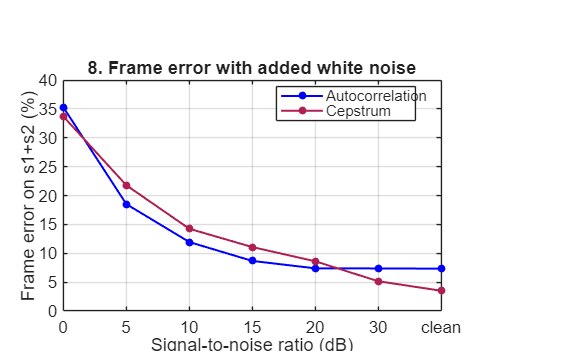

    % 5-frame median filter for a pitch track in which 0 means unvoiced.
    n = numel(pitch);
    keep = movsum(pitch>0,5) >= 3; % Voiced if most of the 5 neighbours are.
    padded = [nan(2,1); pitch; nan(2,1)];
    padded(padded==0) = NaN;
    near = sort(padded((1:n)'+(0:4)),2); % Each row: the 5 neighbours, NaN last.
    middle = max(ceil(sum(~isnan(near),2)/2),1);
    pitch = near(sub2ind(size(near),(1:n)',middle));
    pitch(~keep | isnan(pitch)) = 0;
end

## 8. Three figures that show how the methods work

The show_method function uses a voiced frame near 1.755 s and a quiet frame near 0.205 s of s1. Figure 1 goes from a selected waveform segment to its delayed copy and finally to the correlation peak. It shows the actual idea behind autocorrelation.

Figure 2 puts the voiced and quiet frames next to each other. Their amplitudes, RMS values and correlation curves show why one gets a pitch and the other stays at 0 Hz. The 0.50 correlation line is drawn on the curves.

Figure 3 takes the same two frames through the cepstrum. The voiced frame has a regular ripple on its log spectrum and one sharp cepstral peak at the same period that the autocorrelation found. The quiet frame has no harmonic ripple. The 0.12 line is drawn on the cepstra.

show_method(speech{1},fs,plots);
show_cepstrum(speech{1},fs,plots);

function show_method(x,fs,folder)
    % Two example frames from s1 show how we made the voiced decision.
    [voice,lags,r,voiceRms] = frame_correlation(x,fs,176); % Near 1.755 s
    [quiet,~,rq,quietRms] = frame_correlation(x,fs,21);   % Near 0.205 s
    [period,~] = best_period(lags,r);
    k = round(period); L = numel(voice);

    % Figure 1 follows the signal -> delayed copy -> correlation peak.
    fig = figure('Color','w','Name','1. Autocorrelation extraction');
    subplot(3,1,1);
    plot((0:numel(x)-1)/fs,x); hold on;
    xline(1.735,'r--'); xline(1.775,'r--');
    title('1. Select a 40 ms voiced frame in s1');
    xlabel('Time (s)'); ylabel('Amplitude'); grid on;
    subplot(3,1,2);
    t = (0:L-k-1)/fs*1000;
    plot(t,voice(1:end-k)); hold on; plot(t,voice(k+1:end));
    title(sprintf('2. Compare with a copy delayed by %d samples',k));
    xlabel('Time in frame (ms)'); ylabel('Windowed amplitude');
    legend('Original','Delayed copy'); grid on;
    subplot(3,1,3);
    plot(lags,r); hold on; yline(.5,'m--');
    plot(k,r(lags==k),'ro','MarkerFaceColor','r');
    title(sprintf('3. Correlation peak: lag %.2f, pitch %.1f Hz',period,fs/period));
    xlabel('Lag (samples)'); ylabel('Normalized correlation'); grid on;
    saveas(fig,fullfile(folder,'01_autocorrelation_extraction_s1.png'));

    % Figure 2 compares a clear voiced frame with a quiet frame.
    fig = figure('Color','w','Name','2. Voiced and silent frames');
    frames = {voice,quiet}; curves = {r,rq};
    levels = [voiceRms quietRms]; names = {'Voiced','Silent'};
    for c = 1:2
        subplot(2,2,c);
        plot((0:L-1)/fs*1000,frames{c}); grid on;
        title(sprintf('%s frame: RMS %.4f',names{c},levels(c)));
        xlabel('Time (ms)'); ylabel('Amplitude');
        subplot(2,2,c+2);
        plot(lags,curves{c}); hold on; yline(.5,'m--'); grid on;
        xlabel('Lag (samples)'); ylabel('Normalized correlation');
    end
    sgtitle('Voiced frame receives pitch; silent frame receives 0 Hz');
    saveas(fig,fullfile(folder,'02_voiced_unvoiced_decision_s1.png'));
end

function show_cepstrum(x,fs,folder)
    % The two frames of show_method again, this time through the cepstrum.
    index = [176 21]; names = {'Voiced','Silent'};
    fig = figure('Color','w','Name','3. Cepstrum extraction');
    for c = 1:2
        [frame,lags] = frame_correlation(x,fs,index(c));
        [cep,logSpectrum] = frame_cepstrum(frame,lags);
        subplot(2,2,c);
        plot((0:512)*fs/1024,logSpectrum(1:513)); grid on;
        title(sprintf('%s frame: log spectrum',names{c}));
        xlabel('Frequency (Hz)'); ylabel('log |X(f)|');
        subplot(2,2,c+2);
        plot(lags,cep); hold on; yline(.12,'m--'); grid on;
        [period,strength] = best_period(lags,cep);
        if strength >= .12
            plot(round(period),cep(lags==round(period)),'ro','MarkerFaceColor','r');
            title(sprintf('Cepstral peak: lag %.2f, pitch %.1f Hz',period,fs/period));
        end
        xlabel('Quefrency (samples)'); ylabel('Cepstrum');
    end
    sgtitle('Voiced frame has one cepstral peak; silent frame has none');
    saveas(fig,fullfile(folder,'03_cepstrum_extraction_s1.png'));
end

## 9. How we measured performance

TP means reference voiced and estimated voiced. FP means reference unvoiced but estimated voiced. FN means reference voiced but estimated unvoiced. TN means both say unvoiced.

Voiced precision = TP/(TP+FP). Voiced recall = TP/(TP+FN). For pitch MAE, we average the absolute pitch difference only on TP frames, where both tracks are voiced. The within-20% count checks whether a matched voiced estimate is within 20% of its reference, then prints that count over all reference voiced frames. Missed voiced frames do not count as successes.

To compare the two methods with one number we add the frame error: the share of all frames that are wrong in either way, a voicing mistake (FP or FN) or a matched frame whose pitch is more than 20% off.

methods = {'autocorrelation','autocorrelation','cepstrum','cepstrum'};
smoothing = {'none','median','none','median'};
tracks = {rawAcf,acf,rawCep,cep};
fprintf('\n%-6s %-16s %-9s %4s %3s %3s %4s %10s %7s %9s %11s %12s\n','file','method', ...
        'smoothing','TP','FP','FN','TN','precision','recall','MAE (Hz)','within 20%','frame error');
for s = 1:3 % Row 3 pools s1 and s2.
    if s < 3, use = s; label = sprintf('s%d',s); else, use = 1:2; label = 's1+s2'; end
    for m = 1:4
        score(s,m) = score_track(vertcat(tracks{m}{use}),vertcat(reference{use}));
        S = score(s,m);
        fprintf('%-6s %-16s %-9s %4d %3d %3d %4d %9.1f%% %6.1f%% %9.2f %7d/%-3d %11.1f%%\n', ...
                label,methods{m},smoothing{m},S.tp,S.fp,S.fn,S.tn,S.precision,S.recall, ...
                S.mae,S.within20,S.tp+S.fn,S.frameError);
    end
end

function S = score_track(pitch,reference)
    % Voiced decisions and pitch error of one track against the reference.
    actual = reference > 0; detected = pitch > 0;
    S.tp = sum(actual & detected); S.fp = sum(~actual & detected);
    S.fn = sum(actual & ~detected); S.tn = sum(~actual & ~detected);
    matched = actual & detected; % Compare pitch error where both say voiced.
    S.mae = mean(abs(pitch(matched)-reference(matched)));
    S.within20 = sum(abs(pitch(matched)-reference(matched)) <= ...
                     .2*reference(matched));
    S.precision = 100*S.tp/max(S.tp+S.fp,1);
    S.recall = 100*S.tp/max(S.tp+S.fn,1);
    % A frame is wrong if the voiced decision is wrong or the pitch is over 20% off.
    S.frameError = 100*(S.fp+S.fn+S.tp-S.within20)/numel(reference);
end

## 10. Pitch tracks for all four recordings

Figures 4 and 5 lay both estimates over the supplied reference for s1 and s2. Figures 6 and 7 are the required estimates for s3 and s4, which have no reference: there the two methods can only be checked against each other. The agreement table counts the frames on which both methods make the same voiced decision and, among the frames both call voiced, how many pitch values lie within 5% of each other.

The CSV files contain time_s, autocorrelation_hz, cepstrum_hz and reference_hz, with 0 for an unvoiced frame. The reference column is NaN for s3 and s4. The estimates for s3 and s4 are also saved as p3.mat and p4.mat in the layout of p1.mat and p2.mat.

fprintf('\n%-4s %14s %13s %11s %18s\n','file','same decision','both voiced','within 5%','mean difference');
for s = 1:4
    tableOut = table(time,acf{s},cep{s},reference{s},'VariableNames', ...
                     {'time_s','autocorrelation_hz','cepstrum_hz','reference_hz'});
    writetable(tableOut,fullfile(out,sprintf('s%d_pitch.csv',s)));

    both = acf{s} > 0 & cep{s} > 0;
    gap = abs(acf{s}(both)-cep{s}(both));
    fprintf('s%d %14.1f%% %13d %10.1f%% %15.2f Hz\n',s,100*mean((acf{s}>0)==(cep{s}>0)), ...
            sum(both),100*mean(gap <= .05*(acf{s}(both)+cep{s}(both))/2),mean(gap));
end
p3_autocorrelation = acf{3}; p3_cepstrum = cep{3};
p4_autocorrelation = acf{4}; p4_cepstrum = cep{4};
save(fullfile(out,'p3.mat'),'p3_autocorrelation','p3_cepstrum');
save(fullfile(out,'p4.mat'),'p4_autocorrelation','p4_cepstrum');

for s = 1:4
    fig = figure('Color','w','Name',sprintf('%d. s%d pitch track',s+3,s));
    if s <= 2
        plot(time,gaps(reference{s}),'Color',[.7 .7 .7],'LineWidth',5); hold on;
    end
    plot(time,gaps(acf{s}),'b.-','LineWidth',1.2); hold on;
    plot(time,gaps(cep{s}),'.-','Color',[.69 .12 .32],'LineWidth',1.2);
    if s <= 2
        legend('Provided reference','Autocorrelation','Cepstrum','Location','best');
    else
        legend('Autocorrelation','Cepstrum','Location','best');
    end
    xlabel('Time (s)'); ylabel('Pitch (Hz)');
    title(sprintf('%d. Pitch track for s%d',s+3,s));
    xlim([0 numel(speech{s})/fs]); ylim([0 450]); grid on;
    saveas(fig,fullfile(plots,sprintf('%02d_s%d_pitch_track.png',s+3,s)));
end

function pitch = gaps(pitch)
    % Unvoiced frames (0 Hz) become gaps in the plotted line.
    pitch(pitch==0) = NaN;
end

## 11. Which method copes better with noise

The recordings are clean. To see how each method behaves when they are not, we add white noise to s1 and s2 at a chosen signal-to-noise ratio, measured over the whole recording, and score both methods again with every threshold left as it is. Each noise level is repeated ten times and the frame errors are averaged.

snr = [0 5 10 15 20 30];
repeats = 10;
noisy = zeros(numel(snr),2);
for n = 1:numel(snr)
    for r = 1:repeats
        estimate = {[],[]};
        for s = 1:2
            x = speech{s};
            x = x + sqrt(mean(x.^2)/10^(snr(n)/10))*randn(size(x));
            [~,a] = track_pitch(x,fs); [~,c] = track_pitch_cepstrum(x,fs);
            estimate{1} = [estimate{1}; smooth_track(a)];
            estimate{2} = [estimate{2}; smooth_track(c)];
        end
        for m = 1:2
            S = score_track(estimate{m},vertcat(reference{1:2}));
            noisy(n,m) = noisy(n,m) + S.frameError/repeats;
        end
    end
end
clean = [score(3,2).frameError score(3,4).frameError];
fprintf('\nFrame error on s1+s2 with added white noise (median-filtered tracks)\n');
fprintf('%8s %16s %10s\n','SNR (dB)','autocorrelation','cepstrum');
for n = 1:numel(snr), fprintf('%8d %15.1f%% %9.1f%%\n',snr(n),noisy(n,:)); end
fprintf('%8s %15.1f%% %9.1f%%\n','clean',clean);

fig = figure('Color','w','Name','8. Frame error with added noise');
position = 1:numel(snr)+1;
plot(position,[noisy(:,1); clean(1)],'b.-','LineWidth',1.2,'MarkerSize',14); hold on;
plot(position,[noisy(:,2); clean(2)],'.-','Color',[.69 .12 .32],'LineWidth',1.2,'MarkerSize',14);
xticks(position); xticklabels([compose('%d',snr) {'clean'}]);
legend('Autocorrelation','Cepstrum','Location','best');
xlabel('Signal-to-noise ratio (dB)'); ylabel('Frame error on s1+s2 (%)');
title('8. Frame error with added white noise'); grid on;
saveas(fig,fullfile(plots,'08_frame_error_with_noise.png'));

## 12. What the comparison shows

On the two recordings that have a reference (600 frames), with the median filter on both tracks:

- **Voiced decision.** The cepstrum makes fewer mistakes: 10 frames wrongly called voiced and 9 voiced frames missed, against 15 and 24 for the autocorrelation. Precision is 97.0% against 95.3%, recall 97.3% against 92.7%.

- **Pitch value.** On the frames that a method and the reference both call voiced, the mean absolute error is 3.07 Hz for the cepstrum and 5.00 Hz for the autocorrelation. 320 of the 331 reference voiced frames are within 20% for the cepstrum, 302 for the autocorrelation.

- **Frame error.** 3.5% for the cepstrum and 7.3% for the autocorrelation. The gap is widest on s2, the lower voice (2.0% against 6.7%), where the autocorrelation jumps to twice the pitch for a few frames near 0.26 s (Figure 5). On s1 it is 5.0% against 8.0%.

- **Median filter.** It helps both a little: the frame error falls from 7.8% to 7.3% for the autocorrelation and from 4.3% to 3.5% for the cepstrum.

- **Noise.** With white noise added the order changes (Figure 8). From 20 dB down to 5 dB the autocorrelation has the lower frame error, 11.9% against 14.2% at 10 dB. At 30 dB and on the clean recordings the cepstrum is ahead, and at 0 dB both have failed (about 35%).

- **s3 and s4.** With no reference, the two methods can only be checked against each other. They make the same voiced decision on 97.3% of the frames of s3 and 90.3% of s4, and where both give a pitch the two values lie within 5% of each other on 97.6% and 93.3% of those frames. s3 has a pitch of about 180-280 Hz (median 223 Hz) and s4 about 105-250 Hz (median near 180 Hz). The last three voiced frames of the autocorrelation track of s4 sit near 385 Hz where the cepstrum gives about 105 Hz (Figure 7): there the autocorrelation has locked on to a much shorter lag than the true period.

**Why they differ.** Both curves are searched in the same way, so the difference lies in the curves. The logarithm in the cepstrum flattens the spectrum: the slow shape set by the mouth is pushed to small quefrencies, and the harmonics give one sharp peak that is present for a voiced frame and absent for an unvoiced one (Figure 3). That makes both its voiced decision and its choice of period cleaner on clean speech. The same logarithm gives the weak, noisy parts of the spectrum as much weight as the strong harmonics, so the peak sinks quickly once noise is added. The autocorrelation works on the waveform, where the strong low harmonics dominate. It keeps its peak in noise, but the resonances of the mouth add peaks of their own, and those are where its wrong periods and weaker voiced decisions come from.

**What this does not show.** The thresholds (RMS 0.008, peak heights 0.50 and 0.12, the 82% rule) were chosen on these recordings, so the scores on s1 and s2 are on the optimistic side. Only two recordings, 600 frames, can be scored. The reference is itself the output of a pitch detector (every value in it is 8000 divided by a whole number of samples), so agreeing with it is not quite the same as being right.

**Saved plots.** 01 and 02 explain the autocorrelation, 03 the cepstrum, 04 and 05 lay both tracks over the reference, 06 and 07 are the estimates for s3 and s4, and 08 is the noise test.